# nasa数据集相关性分析

## 健康因子列出来

- 初始放电骤降值

- 3.5~3.8V的等压降时间

- 放电谷底值

- 充电温度差

- 放电温度最大时间点

## 提取健康因子

### 初始放电骤降值

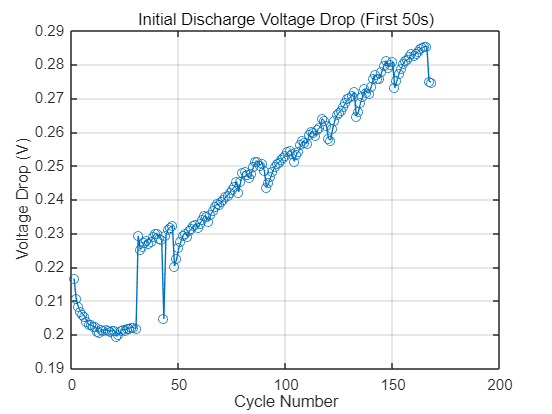

[F1, cyclesF1] = extract_voltage_drop(B0005);



function [F1_list, cycles_list] = extract_voltage_drop(data)
% 提取NASA电池数据集中的初始放电骤降值(F1)和对应循环次数
% 输入:
%   data - 从.mat文件加载的NASA电池数据集结构体
% 输出:
%   F1_list - 每次放电循环前5秒的电压骤降值数组
%   cycles_list - 对应的循环次数数组

F1_list = [];
cycles_list = [];
cycle_count = 0;

% 遍历每个循环
for i = 1:length(data.cycle)
    cycle = data.cycle(i);
    
    % 检查是否是放电循环（根据NASA数据集结构）
    if isfield(cycle, 'type') && strcmpi(cycle.type, 'discharge')
        cycle_count = cycle_count + 1;
        
        % 获取时间、电压数据（字段名根据实际数据调整）
        time = cycle.data.Time; % 时间向量（秒）
        voltage = cycle.data.Voltage_measured; % 电压测量值
        
        % 提取前50秒数据点
        mask = time <= 50;
        time_5s = time(mask);
        voltage_5s = voltage(mask);
        
        if ~isempty(time_5s)
            % 计算初始电压和5秒时的电压差
            initial_voltage = voltage_5s(1);
            [min_voltage, idx] = min(voltage_5s); % 找到前5秒最低电压
            voltage_drop = initial_voltage - min_voltage;
            
            % 存储结果
            F1_list(end+1) = voltage_drop;
            cycles_list(end+1) = cycle_count;
        end
    end
end

% 可视化结果（可选）
figure;
plot(cycles_list, F1_list, '-o');
xlabel('Cycle Number');
ylabel('Voltage Drop (V)');
title('Initial Discharge Voltage Drop (First 50s)');
grid on;
end

### 3.5~3.8V的等压降时间

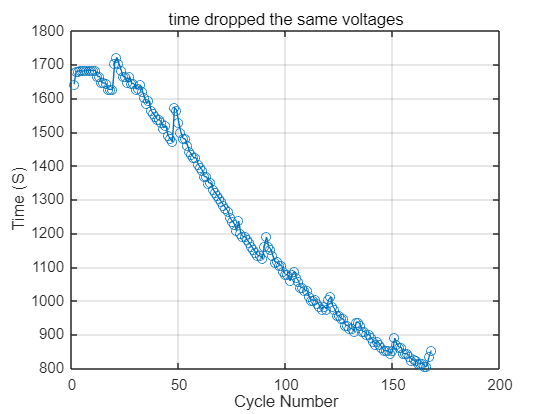

[F2, cyclesF2] = extract_voltage_drop_time(B0005, 3.5, 3.8);

function [time_drop, cycle_list] = extract_voltage_drop_time(data, start_volt, end_volt)
    % 提取3.5~3.8V等压降时间
    % 输入:
    %   data - NASA电池数据集结构体
    %   start_volt - 起始电压(默认3.8V)
    %   end_volt - 结束电压(默认3.5V)
    % 输出:
    %   time_drop - 等压降时间数组
    %   cycle_list - 对应的循环次数数组
    
    if nargin < 3
        start_volt = 3.8;
        end_volt = 3.5;
    end
    
    time_drop = [];
    cycle_list = [];
    cycle_count = 0;
    
    for i = 1:length(data.cycle)
        cycle = data.cycle(i);
        
        % 只处理放电循环
        if strcmp(cycle.type, 'discharge')
            cycle_count = cycle_count + 1;
            voltage = cycle.data.Voltage_measured;
            time = cycle.data.Time;
            
            % 找到电压首次低于start_volt和end_volt的点
            idx_start = find(voltage < end_volt, 1, 'first');
            idx_end = find(voltage < start_volt, 1, 'first');
            
            if ~isempty(idx_start) && ~isempty(idx_end)
                % 计算等压降时间
                drop_time = time(idx_end) - time(idx_start);
                time_drop(end+1) = drop_time;
                cycle_list(end+1) = cycle_count;
            end
        end
    end
end
% 可视化结果（可选）, cycle_list
figure;
plot(cyclesF2, F2, '-o');
xlabel('Cycle Number');
ylabel('Time (S)');
title('time dropped the same voltages');
grid on;

### 充电温度差

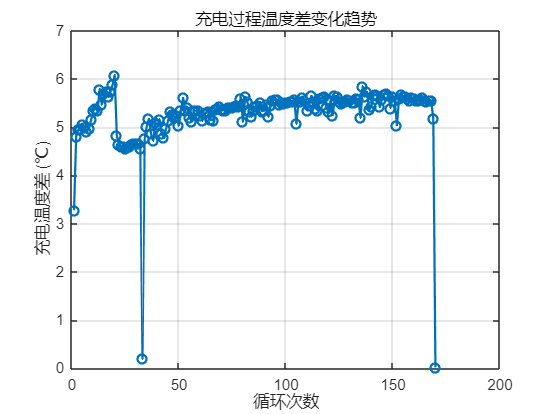

[F5, cyclesF5] = extract_charge_temp_diff(B0005);


function [F5_list, cycles_list] = extract_charge_temp_diff(data)
% 提取NASA电池数据集中的充电温度差(F5)和对应循环次数
% 输入:
%   data - NASA电池数据集结构体（需包含充电循环的温度数据）
% 输出:
%   F5_list - 每次充电循环的最大温度差数组（℃）
%   cycles_list - 对应的循环次数数组

F5_list = [];
cycles_list = [];
cycle_count = 0;

% 检查输入数据结构
if ~isfield(data, 'cycle')
    error('输入数据结构不正确，缺少cycle字段');
end

% 遍历每个循环
for i = 1:length(data.cycle)
    current_cycle = data.cycle(i);
    
    % 只处理充电循环
    if isfield(current_cycle, 'type') && strcmpi(current_cycle.type, 'charge')
        cycle_count = cycle_count + 1;
        
        % 检查温度数据是否存在
        if isfield(current_cycle.data, 'Temperature_measured')
            temp_data = current_cycle.data.Temperature_measured;
            time_data = current_cycle.data.Time;
            
            % 计算充电过程中的温度差（最大值-最小值）
            if ~isempty(temp_data)
                temp_diff = max(temp_data) - min(temp_data);
                
                % 存储结果
                F5_list(end+1) = temp_diff;
                cycles_list(end+1) = cycle_count;
            end
        end
    end
end

% 数据可视化（可选）
if ~isempty(F5_list)
    figure;
    plot(cycles_list, F5_list, '-o', 'LineWidth', 1.5);
    xlabel('循环次数');
    ylabel('充电温度差 (℃)');
    title('充电过程温度差变化趋势');
    grid on;
end
end

### 放电电压谷底对应时间

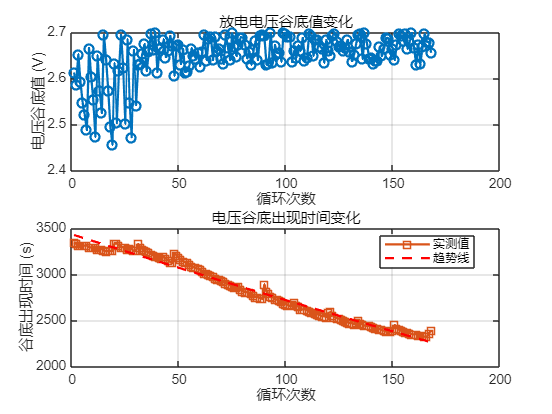

[F3, F4, cyclesF3F4] = extract_discharge_valley_time(B0005 );

function [min_voltages, valley_times, cycles] = extract_discharge_valley_time(data)
% 提取每次放电循环中的电压谷底值及其出现时间
% 输入:
%   data - NASA电池数据集结构体
% 输出:
%   min_voltages - 电压谷底值数组(V)
%   valley_times - 谷底值对应的时间数组(s)
%   cycles - 对应的循环次数数组

% 初始化输出变量
min_voltages = [];
valley_times = [];
cycles = [];
cycle_count = 0;

% 检查输入数据结构
if ~isfield(data, 'cycle')
    error('输入数据结构不正确，缺少cycle字段');
end

% 遍历每个循环
for i = 1:length(data.cycle)
    current_cycle = data.cycle(i);
    
    % 只处理放电循环
    if isfield(current_cycle, 'type') && strcmpi(current_cycle.type, 'discharge')
        cycle_count = cycle_count + 1;
        
        % 检查必要字段
        if ~isfield(current_cycle.data, 'Voltage_measured') || ...
           ~isfield(current_cycle.data, 'Time')
            warning('循环%d缺少电压或时间数据，已跳过', cycle_count);
            continue;
        end
        
        % 获取电压和时间数据
        voltage = current_cycle.data.Voltage_measured;
        time = current_cycle.data.Time;
        
        % 找到电压谷底值及其时间点
        [min_voltage, idx] = min(voltage);
        valley_time = time(idx);
        
        % 存储结果
        min_voltages(end+1) = min_voltage;
        valley_times(end+1) = valley_time;
        cycles(end+1) = cycle_count;
    end
end

% 数据可视化
if ~isempty(min_voltages)
    figure;
    
    % 电压谷底值变化趋势
    subplot(2,1,1);
    plot(cycles, min_voltages, '-o', 'LineWidth', 1.5);
    xlabel('循环次数');
    ylabel('电压谷底值 (V)');
    title('放电电压谷底值变化');
    grid on;
    
    % 谷底出现时间变化趋势
    subplot(2,1,2);
    plot(cycles, valley_times, '-s', 'LineWidth', 1.5, 'Color', [0.85 0.33 0.1]);
    xlabel('循环次数');
    ylabel('谷底出现时间 (s)');
    title('电压谷底出现时间变化');
    grid on;
    
    % 添加趋势线（二次多项式拟合）
    hold on;
    p = polyfit(cycles, valley_times, 2);
    trend = polyval(p, cycles);
    plot(cycles, trend, 'r--', 'LineWidth', 1.5);
    legend('实测值', '趋势线', 'Location', 'best');
    hold off;
end
end


### 放电温度最大时间点

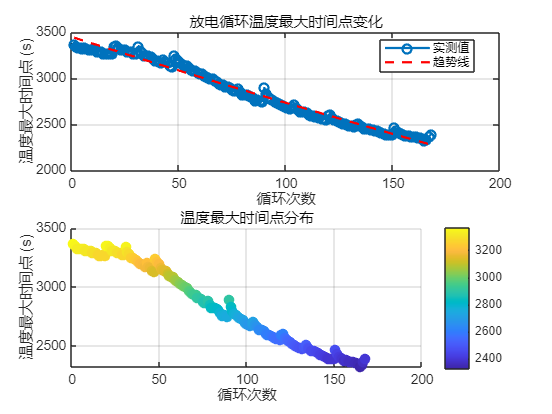

[F6, cyclesF6] = extract_max_temp_time(B0005);

function [max_temp_times, cycles] = extract_max_temp_time(data)
% 提取每次放电循环中温度达到最大值的时间点
% 输入:
%   data - NASA电池数据集结构体
% 输出:
%   max_temp_times - 温度最大值对应的时间点数组(s)
%   cycles - 对应的循环次数数组

max_temp_times = [];
cycles = [];
cycle_count = 0;

% 检查输入数据结构
if ~isfield(data, 'cycle')
    error('输入数据结构不正确，缺少cycle字段');
end

% 遍历每个循环
for i = 1:length(data.cycle)
    current_cycle = data.cycle(i);
    
    % 只处理放电循环
    if isfield(current_cycle, 'type') && strcmpi(current_cycle.type, 'discharge')
        cycle_count = cycle_count + 1;
        
        % 检查必要字段
        if ~isfield(current_cycle.data, 'Temperature_measured') || ...
           ~isfield(current_cycle.data, 'Time')
            warning('循环%d缺少温度或时间数据，已跳过', cycle_count);
            continue;
        end
        
        % 获取温度和时间数据
        temperature = current_cycle.data.Temperature_measured;
        time = current_cycle.data.Time;
        
        % 找到温度最大值及其时间点
        [max_temp, idx] = max(temperature);
        max_time = time(idx);
        
        % 存储结果
        max_temp_times(end+1) = max_time;
        cycles(end+1) = cycle_count;
    end
end

% 数据可视化
if ~isempty(max_temp_times)
    figure;
    
    % 温度最大时间点变化趋势
    subplot(2,1,1);
    plot(cycles, max_temp_times, '-o', 'LineWidth', 1.5);
    xlabel('循环次数');
    ylabel('温度最大时间点 (s)');
    title('放电循环温度最大时间点变化');
    grid on;
    
    % 添加趋势线（二次多项式拟合）
    hold on;
    p = polyfit(cycles, max_temp_times, 2);
    trend = polyval(p, cycles);
    plot(cycles, trend, 'r--', 'LineWidth', 1.5);
    legend('实测值', '趋势线', 'Location', 'best');
    hold off;
    
    % 温度最大值与时间点关系
    subplot(2,1,2);
    scatter(cycles, max_temp_times, 50, max_temp_times, 'filled');
    xlabel('循环次数');
    ylabel('温度最大时间点 (s)');
    title('温度最大时间点分布');
    colorbar;
    grid on;
end
end

### ## 电池容量

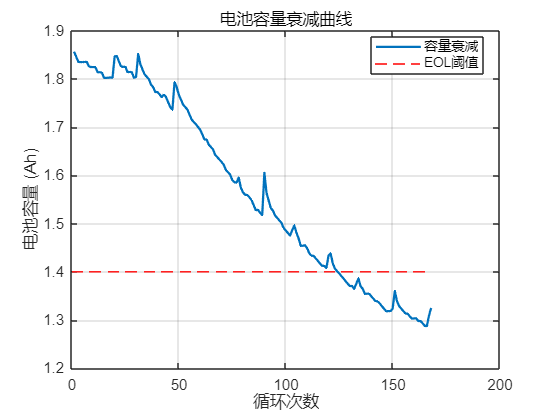

capacity =     1.8565    1.8463    1.8353    1.8353    1.8346    1.8357    1.8351    1.8258    1.8248    1.8246    1.8246    1.8142    1.8138    1.8134    1.8026    1.8021    1.8026    1.8031    1.8028    1.8470    1.8474    1.8362    1.8258    1.8251    1.8256    1.8140    1.8148    1.8140    1.8028    1.8041    1.8518    1.8307    1.8199    1.8093    1.8046    1.7994    1.7884    1.7829    1.7730    1.7730    1.7679    1.7623    1.7676    1.7627    1.7517    1.7418    1.7361    1.7936    1.7832    1.7674


cycles =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


[capacity, cycles] = extract_battery_capacity(B0005)

function [capacity, cycles] = extract_battery_capacity(data)
% 提取NASA电池数据集中的放电容量及对应循环次数
% 输入:
%   data - NASA电池数据集结构体（需包含放电循环的容量数据）
% 输出:
%   capacity - 每次放电循环的容量数组（Ah）
%   cycles - 对应的循环次数数组（一次充放电记为一次循环）

capacity = [];
cycles = [];
cycle_count = 0;

% 检查输入数据结构
if ~isfield(data, 'cycle')
    error('输入数据结构不正确，缺少cycle字段');
end

% 遍历每个循环
for i = 1:length(data.cycle)
    current_cycle = data.cycle(i);
    
    % 只处理放电循环（根据NASA数据集定义）
    if isfield(current_cycle, 'type') && strcmpi(current_cycle.type, 'discharge')
        cycle_count = cycle_count + 1;
        
        % 检查容量数据是否存在
        if isfield(current_cycle.data, 'Capacity')
            current_capacity = current_cycle.data.Capacity(1); % 取第一个容量值
            capacity(end+1) = current_capacity;
            cycles(end+1) = cycle_count;
        else
            warning('循环%d缺少容量数据，已跳过', cycle_count);
        end
    end
end

% 数据可视化（可选）
if ~isempty(capacity)
    figure;
    plot(cycles, capacity, '-', 'LineWidth', 1.5);
    xlabel('循环次数');
    ylabel('电池容量 (Ah)');
    title('电池容量衰减曲线');
    grid on;
    
    % 标注寿命终止点（EOL，容量降至初始值的70%）
    hold on;
    eol_threshold = 2.0 * 0.7; % NASA定义EOL为2Ah的70%（即1.4Ah）
    plot([0, max(cycles)], [eol_threshold, eol_threshold], 'r--');
    legend('容量衰减', 'EOL阈值', 'Location', 'best');
    hold off;
end
end

## 相关性分析

F5 = F5(1:168);
cyclesF5 = cyclesF5(1:168);
data = [F1',F2',F3',F4',F5',F6'];

standardized_data = zscore(data);
correlation_matrix = corr(standardized_data)

correlation_matrix =     1.0000   -0.9770    0.5555   -0.9708    0.4067   -0.9724
   -0.9770    1.0000   -0.5156    0.9968   -0.4716    0.9970
    0.5555   -0.5156    1.0000   -0.4914    0.1584   -0.4944
   -0.9708    0.9968   -0.4914    1.0000   -0.4748    0.9999
    0.4067   -0.4716    0.1584   -0.4748    1.0000   -0.4736
   -0.9724    0.9970   -0.4944    0.9999   -0.4736    1.0000


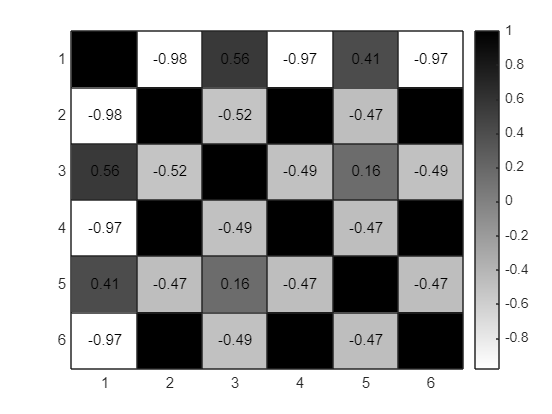

% 可视化相关系数矩阵
% 生成示例数据，假设我们有 100 个样本，6 个

% 创建一个图形窗口
figure('Position', [100, 100, 800, 600]);

% 绘制热力图
h = heatmap(correlation_matrix);


% 设置颜色映射，使用自定义的颜色方案
colormap(flipud(gray));

% 显示网格线
h.GridVisible = 'on';

% 调整热力图的单元格样式
h.CellLabelColor = 'k';
h.CellLabelFormat = '%.2f';    

### 各个健康因子和电磁容量的相关性分析

corr_data = [];
for i= 1 :6
    data1 = [data(:,i),capacity'];

    standardized_data1 = zscore(data1);
    correlation_matrix1 = corr(standardized_data1);
    corr_data(i) = correlation_matrix1(1,2);
end
disp(corr_data);

   -0.9688    0.9962   -0.4871    0.9999   -0.4755    0.9998



## 主成分分析

% 进行主成分分析
[coeff, score, latent] = pca(standardized_data(:,[1 2 4 6]));

% 显示主成分系数矩阵
disp('主成分系数矩阵:');

主成分系数矩阵:


disp(coeff);

   -0.4953    0.8614    0.1108    0.0215
    0.5017    0.1795    0.8461    0.0079
    0.5013    0.3527   -0.3655   -0.7004
    0.5016    0.3184   -0.3717    0.7134




% 显示主成分得分矩阵
disp('主成分得分矩阵:');

主成分得分矩阵:


disp(score);

    2.7232    0.3344   -0.0912    0.0150
    2.8489    0.1228    0.0300    0.0104
    2.8393    0.0047    0.0629    0.0075
    2.8675   -0.0387    0.0597    0.0062
    2.8753   -0.0698    0.0578    0.0056
    2.8933   -0.0888    0.0528    0.0050
    2.9207   -0.1424    0.0480    0.0036
    2.8931   -0.2058    0.0863    0.0023
    2.8857   -0.2102    0.0852    0.0020
    2.8979   -0.2268    0.0839    0.0018
    2.8981   -0.2267    0.0842    0.0017
    2.8369   -0.3183    0.0692   -0.0006
    2.8435   -0.3298    0.0695   -0.0010
    2.7967   -0.3180    0.0202   -0.0008
    2.7436   -0.3618    0.0605   -0.0018
    2.7326   -0.3556    0.0598   -0.0017
    2.7126   -0.3777    0.0087   -0.0024
    2.7160   -0.3798    0.0067   -0.0027
    2.7115   -0.3751    0.0069   -0.0023
    3.0672   -0.1723    0.0488    0.0031
    3.1375   -0.2194    0.0929    0.0020
    3.0357   -0.2460    0.0864    0.0015
    2.9289   -0.2597    0.0769    0.0013
    2.8844   -0.2604    0.0273    0.0007
    2.8934   -0.


% 显示每个主成分的方差
disp('每个主成分的方差:');

每个主成分的方差:


disp(latent);

    3.9571
    0.0393
    0.0035
    0.0000




% 计算每个主成分的贡献率
explained_variance_ratio = latent / sum(latent);

% 显示每个主成分的贡献率
disp('每个主成分的贡献率:');

每个主成分的贡献率:


disp(explained_variance_ratio);

    0.9893
    0.0098
    0.0009
    0.0000



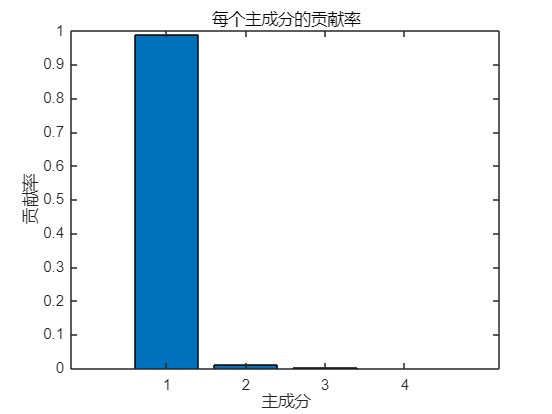


% 绘制每个主成分的贡献率柱状图
figure;
bar(explained_variance_ratio);
title('每个主成分的贡献率');
xlabel('主成分');
ylabel('贡献率');

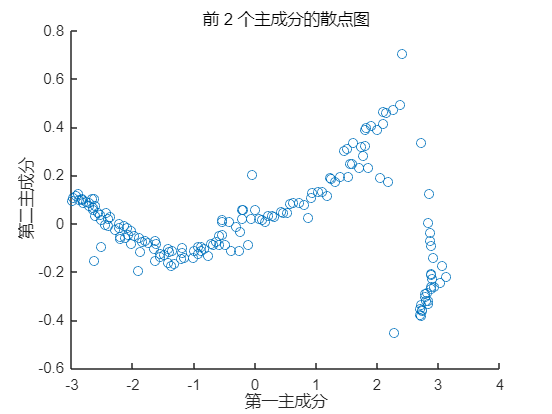


% 选择前 2 个主成分进行可视化
figure;
scatter(score(:, 1), score(:, 2));
title('前 2 个主成分的散点图');
xlabel('第一主成分');
ylabel('第二主成分');

LSTM网络

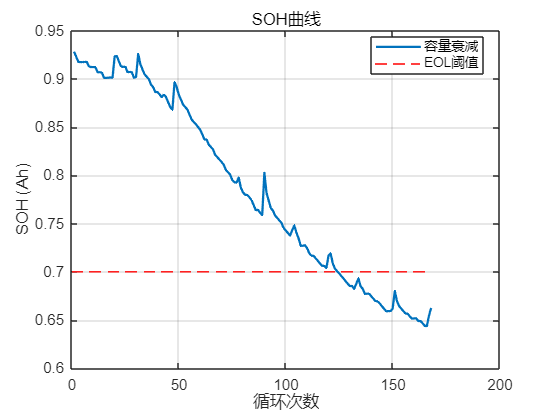

[SOH, cycles] = SOHGet(B0005);


function [SOH, cycles] = SOHGet(data)
% 提取NASA电池数据集中的放电容量及对应循环次数
% 输入:
%   data - NASA电池数据集结构体（需包含放电循环的容量数据）
% 输出:
%   capacity - 每次放电循环的容量数组（Ah）
%   cycles - 对应的循环次数数组（一次充放电记为一次循环）

capacity = [];
SOH =[];
cycles = [];
cycle_count = 0;

% 检查输入数据结构
if ~isfield(data, 'cycle')
    error('输入数据结构不正确，缺少cycle字段');
end

% 遍历每个循环
for i = 1:length(data.cycle)
    current_cycle = data.cycle(i);
    
    % 只处理放电循环（根据NASA数据集定义）
    if isfield(current_cycle, 'type') && strcmpi(current_cycle.type, 'discharge')
        cycle_count = cycle_count + 1;
        
        % 检查容量数据是否存在
        if isfield(current_cycle.data, 'Capacity')
            current_capacity = current_cycle.data.Capacity(1); % 取第一个容量值
            capacity(end+1) = current_capacity;
            SOH(end+1) = current_capacity/2;
            cycles(end+1) = cycle_count;
        else
            warning('循环%d缺少容量数据，已跳过', cycle_count);
        end
    end
end


    figure;
    plot(cycles, SOH, '-', 'LineWidth', 1.5);
    xlabel('循环次数');
    ylabel('SOH (Ah)');
    title('SOH曲线');
    grid on;
    
    % 标注寿命终止点（EOL，容量降至初始值的70%）
    hold on;
    eol_threshold =  0.7; % NASA定义EOL为2Ah的70%（即1.4Ah）
    plot([0, max(cycles)], [eol_threshold, eol_threshold], 'r--');
    legend('容量衰减', 'EOL阈值', 'Location', 'best');
    hold off;

end